clc; clear; close all;
%funcion para crear ventana deseada(un PB antitransformado)
h= @(nm, wc, N)( (wc/pi) .* sinc((wc/pi) .* (nm - N/2)) );

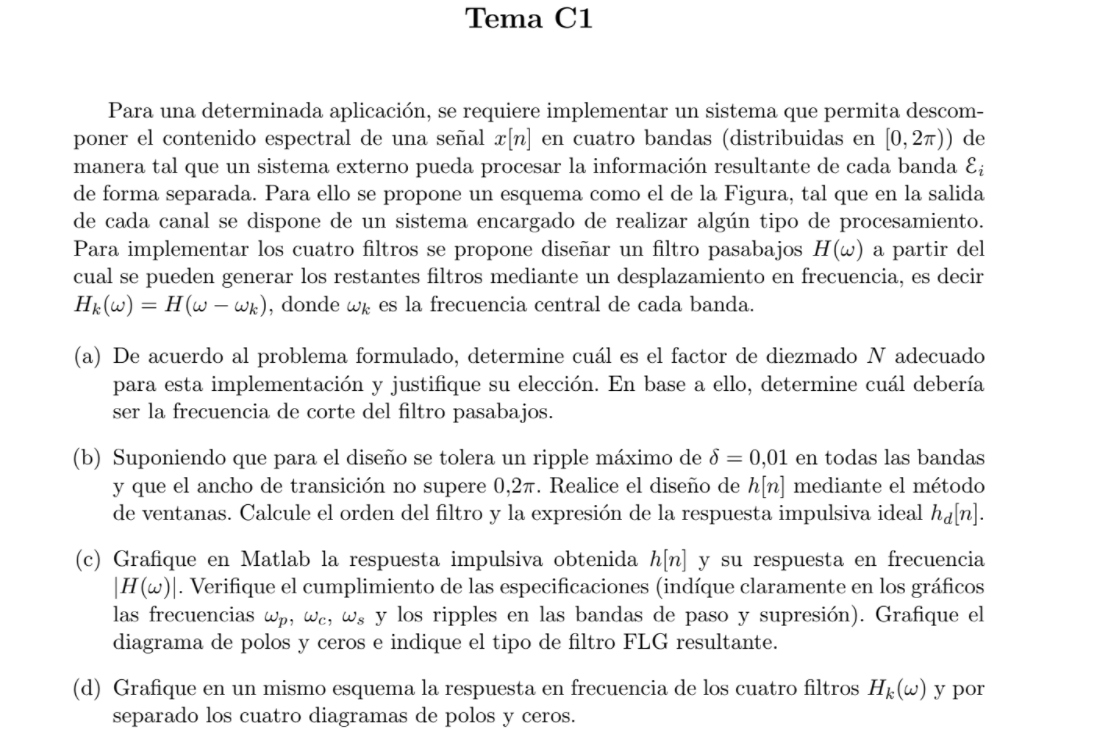

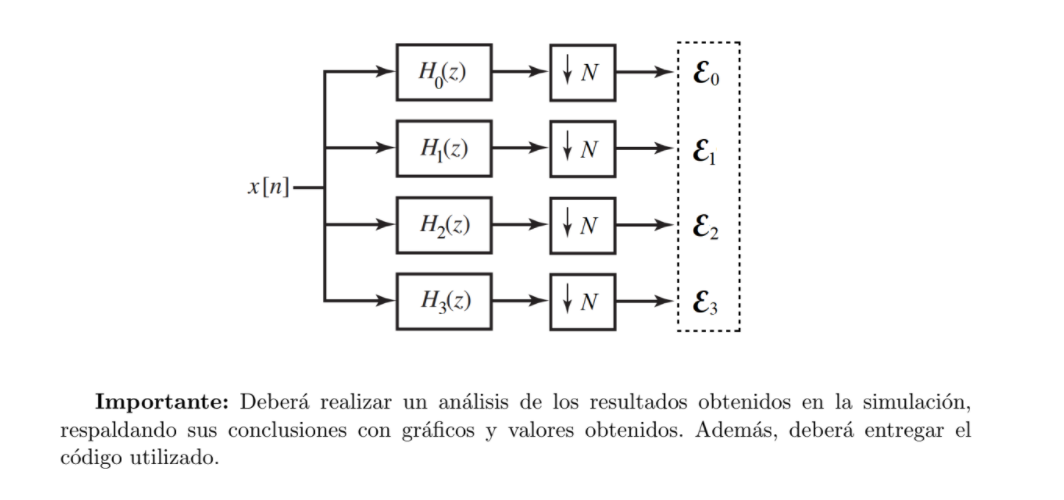

Para que la señal se descomponga en 4 sub-bandas entonces debe haber 4 filtros que cada una tenga un separados en $2\frac{\pi}{3}k$ con $M=4$ donde la frecuencia de corte del primer filtro será $w_c = \pi/3$

% _a)_
%Hk(w) = H0( w - 2.PI.k/M )
M = 4 % tal que 

M = 4

%frecuencia de corte ideal:
wc = pi/3; %idealmente
%pero si quiero hasta pi/3 ~sin atenueacion-->wp = pi/3
wp = pi/3;
%wp = wp/2;

% _b)_
delta = 0.01;               % ripple de rechazo y paso
Dw = 0.2*pi                 %ancho de banda de transición

Dw = 0.6283

wc = wp + Dw/2

wc = 1.3614

Ripple_dB = 20*log10(delta) %-40dB

Ripple_dB = -40

%Hammin Dw = 8pi/M, ripple=  -41dB
M_ = ceil(8*pi/Dw)

M_ = 40

N = M_-1;
%numero de muestras.
nfft = 8192;
%Vector de frecuencias.
w = linspace(0, 2*pi, nfft);

%Ventanas a Hann.
w_hamm = window(@hamming, N+1)';
%Creo mi filtro PB con la ventana
h_ideal = h(0:N, wc, N);
h_hamm = h_ideal.*w_hamm

h_hamm =     0.0013    0.0001   -0.0018   -0.0012    0.0027    0.0038   -0.0030   -0.0084    0.0006    0.0145    0.0067   -0.0198   -0.0211    0.0205    0.0449   -0.0098   -0.0844   -0.0317    0.1866    0.4000    0.4000    0.1866   -0.0317   -0.0844   -0.0098    0.0449    0.0205   -0.0211   -0.0198    0.0067    0.0145    0.0006   -0.0084   -0.0030    0.0038    0.0027   -0.0012   -0.0018    0.0001    0.0013


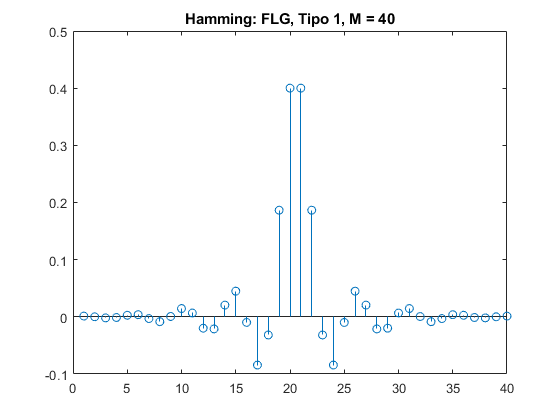

% FFT del filtro.
H_hamm = fft(h_hamm, nfft);

% Respuesta en el tiempo de las ventanas
figure
stem(h_hamm), title('Hamming: FLG, Tipo 1, M = 40')%%% xlim([-29 N+30]), ylim([0 1.2])

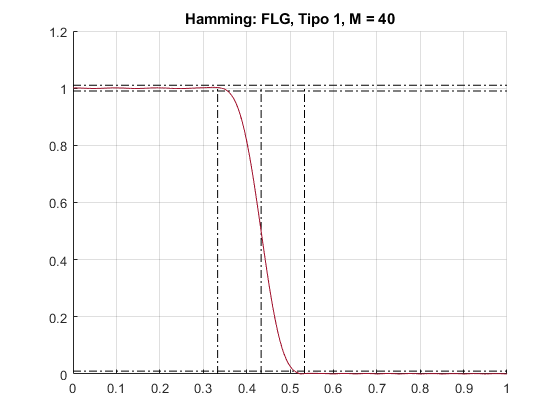


figure()
hold on;
plot([wp wp]./pi, [0 1], '-.k')
plot([wc wc]./pi, [0 1], '-.k')
plot([wp + Dw wp + Dw]./pi, [0 1], '-.k')

plot([0 1], [delta delta], '-.k')
plot([0 1], [1 + delta 1 + delta], '-.k')
plot([0 1], [1 - delta 1 - delta], '-.k')

plot(w/pi, abs(H_hamm))
title('Hamming: FLG, Tipo 1, M = 40')
xlim([0 1])
grid on

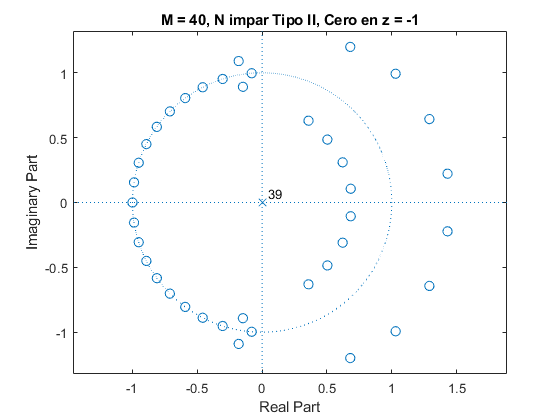


figure()
zplane(h_hamm)
title("M = 40, N impar Tipo II, Cero en z = -1")

%N = 39, M = 40, es tipo II, 

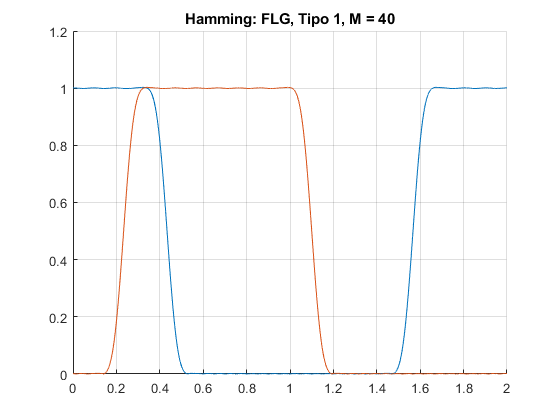

%Luego el resto de los filtros serán: e^-jWno X(W) -> x(n - n0)
n = 0:N;
h0 = h_hamm;
%e^jw.pi h0(w)
w1 = 2*pi/(M-1);   
h1 = exp(j*w1*n).*h0;


figure()
hold on
plot(w/pi, abs(fft(h0, nfft)))
plot(w/pi, abs(fft(h1, nfft)))
title('Hamming: FLG, Tipo 1, M = 40')
xlim([0 2])
grid on